## Assignment 4

Authors:

Kolja Westphal (455887) 

Thineth Gamage (456727)

Tristan de le Cruz Hachiles (405541)

% Class Objects
OM = OrbitManeuver;
warning('off','all')

## Task 1: Special Maneuver: Phasing

Below we calculate the total detla_v for a phasing maneuver from inclined LEO orbit to GEO using a phasing orbit to time the interception, 

first only with in inclination burn when intercepting the target and in the second subtask, we split the inclination burn before and after the transfer

% Constants and definition of LEO and GEO orbit
mu_earth          = 398600.440;            % km³/s²
Re_earth          = 6371;                  % km
% Interceptor LEO
h_leo       = 200;                   % km
a_leo       = h_leo + Re_earth;            % km
i_leo       = deg2rad(22.5);         % rad
RAAN_leo    = deg2rad(40);           % rad
u_t0        = deg2rad(17);           % rad

% Target GEO
h_geo       = 35786;                 % km
a_geo       = Re_earth + h_geo;            % km
lambda_t0   = deg2rad(200);          % rad


### Task 1a)

### Task 1b)

## Task 2: High-thrust maneuver using optimization

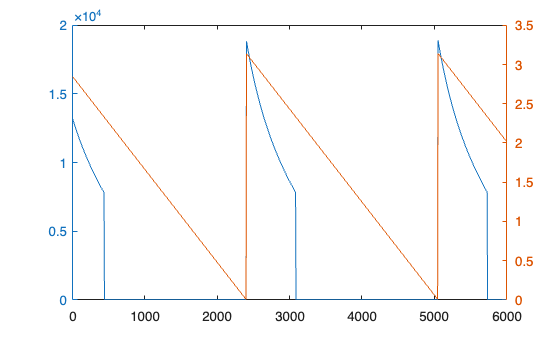

% -----------------------------
% Task 2: Two-impulse LEO->GEO transfer (high thrust)
% Study how the waiting time t_w changes:
%  - the injection geometry (angle to node nu)
%  - the transfer time of flight (t_trans)
% Then evaluate an optimization sweep for the full 2-impulse transfer.
% -----------------------------

% Determine relevant parameters for transfer orbit (Hohmann Transfer)
r_initial = a_leo;   % initial orbit radius (LEO)
r_target  = a_geo;   % target orbit radius (GEO)

% Angular velocity (mean motion) for initial and target circular orbits
omega_initial = sqrt(mu_earth / r_initial^3);
omega_target  = sqrt(mu_earth / r_target^3);

% Geometry: angle to the node for the interceptor at burn time
% u(t) = u_t0 + omega_initial*t_w  (argument of latitude propagation)
% mod(..., pi) introduces periodicity and jump discontinuities every pi
nu = @(t_w) pi - mod(u_t0 + omega_initial * t_w, pi);

% Sweep waiting times (here in seconds, from ~1 to 6000)
x = linspace(1, 6.0E3, 1000);

t_trans = zeros(size(x));  % store transfer time of flight results
nu_all  = zeros(size(x));  % store node-angle results

for k = 1:length(x)

    % Compute transfer time for a given waiting time via the one-tangent burn routine
    % Note: nu(x(k)) changes discontinuously due to mod(...,pi), which can propagate into the transfer solution and cause the sawtooth shape in results.
    [~, ~, ~, ~, ~, t_trans(k)] = OM.one_tangent_burn_LEO_GEO( ...
        a_leo, a_geo, nu(x(k)), mu_earth);

    % Store the angle to node used in this iteration
    nu_all(k) = nu(x(k));

end

% Plot sweep: left axis transfer time, right axis geometry angle nu
figure
yyaxis left
plot(x, t_trans)
yyaxis right
plot(x, nu_all)

The waiting-time sweep shows a periodic, sawtooth-like behaviour in the node-angle nu. This is caused by the modulo operation mod(⋅,π), which wraps the propagated argument of latitude every π\piπ radians. At these wrap points, nu changes discontinuously, which leads to corresponding discontinuities in the computed transfer time t_trans�. Therefore, the blue curve is not a smooth function of t_w�, but consists of piecewise segments separated by jumps where the geometry is re-wrapped.

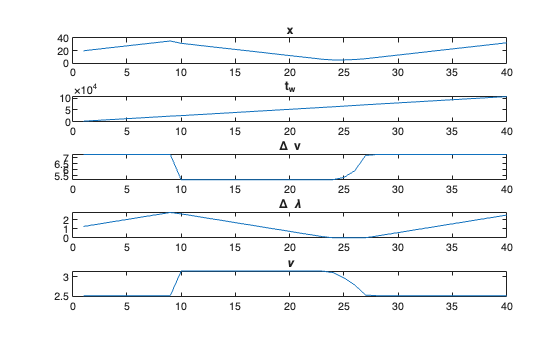

% Run the full two-impulse transfer evaluation/optimization
% The last argument "40" seems to be number of samples / iterations for the sweep
[x_all, t_w_all, delta_v_all, delta_lambda_all, nu_opt_all] = OM.perform_two_impulse_transfer(a_leo, i_leo, RAAN_leo, a_geo, 0, lambda_t0, u_t0, mu_earth, 40);


figure
subplot(5,1,1), plot(x_all), title('x')
subplot(5,1,2), plot(t_w_all), title('t_w')
subplot(5,1,3), plot(delta_v_all), title('\Delta v')
subplot(5,1,4), plot(delta_lambda_all), title('\Delta \lambda')
subplot(5,1,5), plot(nu_opt_all), title('\nu')

The plots show the results of the parameter sweep for the two-impulse transfer. The waiting time twt_wtw� covers the investigated range, while the total velocity change Δv stays within a relatively small interval. This indicates that the required maneuver cost is only weakly influenced by small changes in the waiting time for this transfer setup.

In contrast, the longitude difference Δλ changes more strongly with t_w�. This is caused by the continuous rotation of the GEO target during the waiting and transfer phases. As a result, small variations in the arrival time can lead to noticeable changes in the longitude mismatch.

The node angle nu shows piecewise behaviour with sudden jumps. This is a consequence of the modulo operation used in its calculation, which introduces discontinuities when the angle is wrapped.